## Simplifying circuits

ELAB can recursively simplify your circuit, updating the entire circuit object in the process.

We start by loading a circuit from a text file and displaying its netlist. This circuit is arbitrary and could be of any size and shape. The circuit is then analyzed and some results are displayed.

circuit = Circuit('circuits/passive/c9_series_parallel.txt');
circuit.list

ans =     'V1 1 0 AC 10
     R1 1 2 1000
     R2 2 0 2000
     R3 2 0 2000
     R4 1 2 3000
     R5 1 0 1000
     C1 1 0 2
     C2 0 1 3
     C3 1 0 5
     '


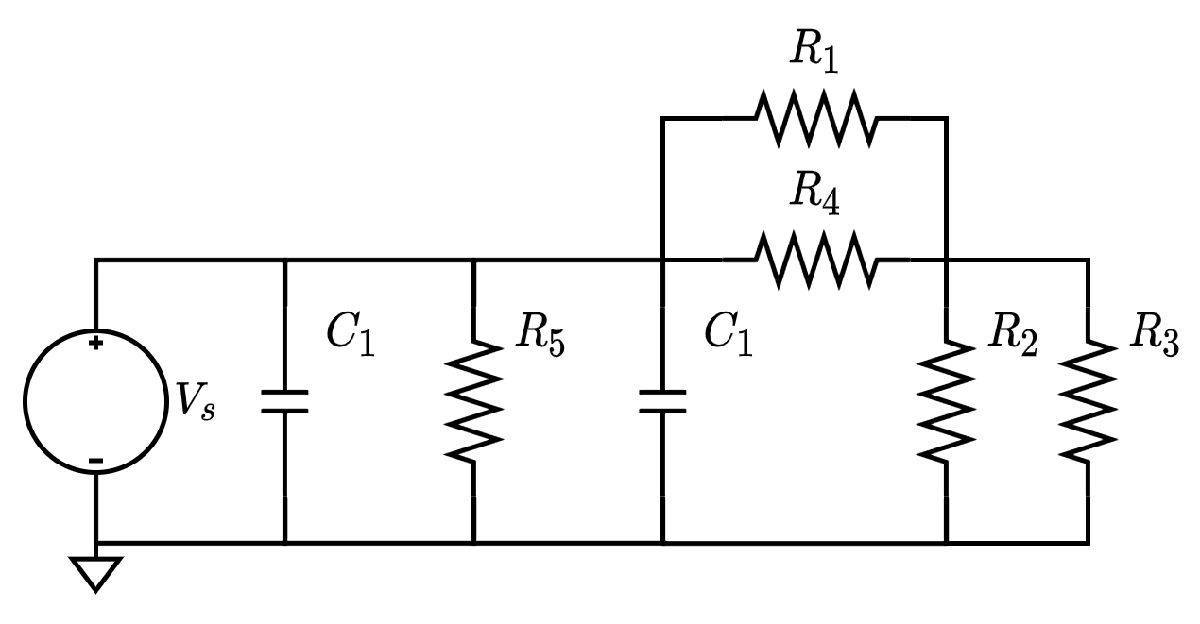

ELAB.analyze(circuit)

Symbolic analysis successful (0.789238 sec).


circuit.symbolic_node_voltages

$$ans = \left(\begin{array}{c} v_{1}=V_{1}\\ v_{2}=\frac{R_{2}\,R_{3}\,V_{1}\,\left(R_{1}+R_{4}\right)}{R_{1}\,R_{2}\,R_{3}+R_{1}\,R_{2}\,R_{4}+R_{1}\,R_{3}\,R_{4}+R_{2}\,R_{3}\,R_{4}} \end{array}\right)$$

We then simplify the circuit and repeat the process. Notice, that the naming and orientation of individual elements are accounted for.

ELAB.simplify(circuit);
circuit.list

ans =     'V1 1 0 AC 10
     Req 1 0 7000/11
     Ceq 1 0 10
     '


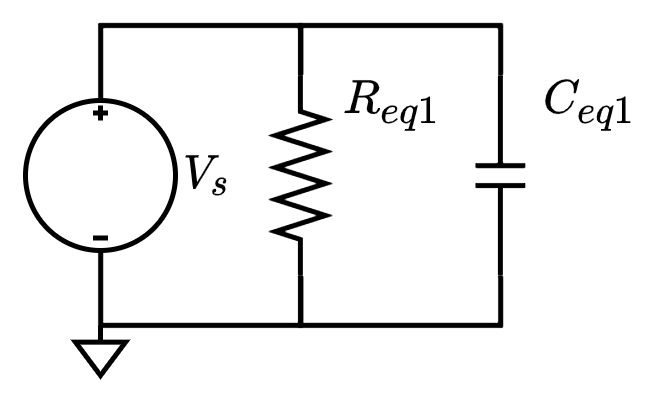

ELAB recursively simplified the series and parallel resistors and capacitors, calculating their new values and giving them new names. Since all the resistors and capacitors can be reduced to a single resistor and capacitor in parallel, the node voltage at node 1 is simply the source voltage. 

ELAB.analyze(circuit)

Symbolic analysis successful (0.233615 sec).


circuit.symbolic_node_voltages

$$ans = v_{1}=V_{1}$$

Let's check if it was done right. From the pre-simplify diagram, we see that the resistors simplify to:

 
$$\begin{array}{l}
R_{\textrm{eq1}} =\left(\left(R_1 ||R_4 \right)+\left(R_2 ||R_3 \right)\right)||R_5 \\
\;\;\;\;\;\;\;\;=\frac{\left(\left(\frac{1k\Omega \cdot 3k\Omega }{1k\Omega +3k\Omega }\right)+\left(\frac{2k\Omega \cdot 2k\Omega }{2k\Omega +2k\Omega }\right)\right)\cdot 1k\Omega }{\left(\left(\frac{1k\Omega \cdot 3k\Omega }{1k\Omega +3k\Omega }\right)+\left(\frac{2k\Omega \cdot 2k\Omega }{2k\Omega +2k\Omega }\right)\right)+1k\Omega }\\
\;\;\;\;\;\;\;\;=7k\Omega /11
\end{array}$$


And the capacitors simplify to:


$$\begin{array}{l}
C_{\textrm{eq1}} =C_1 ||C_2 \\
\;\;\;\;\;\;\;\;=C_1 +C_2 \\
\;\;\;\;\;\;\;\;=5
\end{array}$$


ELABorate can simplify series and parallels of any 2-terminal element.

Here are examples of how a larger number of series and parallels are handled.

circuit = Circuit('circuits/passive/c15_triple_parallel.txt');
circuit.list

ans =     'Vs 1 0 DC 12
     R1 1 0 3000
     R2 1 0 4000
     R3 1 0 2000
     '


ELAB.simplify(circuit);
circuit.list

ans =     'Vs 1 0 DC 12
     Req 1 0 12000/13
     '


circuit = Circuit('circuits/passive/c16_triple_series.txt');
circuit.list

ans =     'Vs 1 0 DC 12
     R1 1 2 3000
     R2 2 3 4000
     R3 3 0 2000
     '


ELAB.simplify(circuit);
circuit.list

ans =     'Vs 1 0 DC 12
     Req 1 0 9000
     '


circuit = Circuit('circuits/passive/c18_quad_series.txt');
circuit.list

ans =     'Vs 1 0 DC 12
     R1 1 2 3000
     R2 2 3 4000
     R3 3 4 2000
     R4 4 0 1000
     '


ELAB.simplify(circuit);
circuit.list

ans =     'Vs 1 0 DC 12
     Req 1 0 10000
     '
